# Steady Heat Conduction in Block with Cooling Pipes

This demo explores the cooling of a heat-producing block via conduction from a variable number and size of cooling pipes. Experiment with the number of pipes, the diameters of the pipes, and the mass flow rate to see how the maximum temperature of the block is affected. This has applications in Electric Vehicles, for example in the design of cold plates for [battery thermal analysis](https://www.mathworks.com/help/pde/ug/reduced-order-model-for-battery-thermal-behavior.html) and [battery thermal management systems](https://www.mathworks.com/discovery/battery-thermal-management-system.html). 

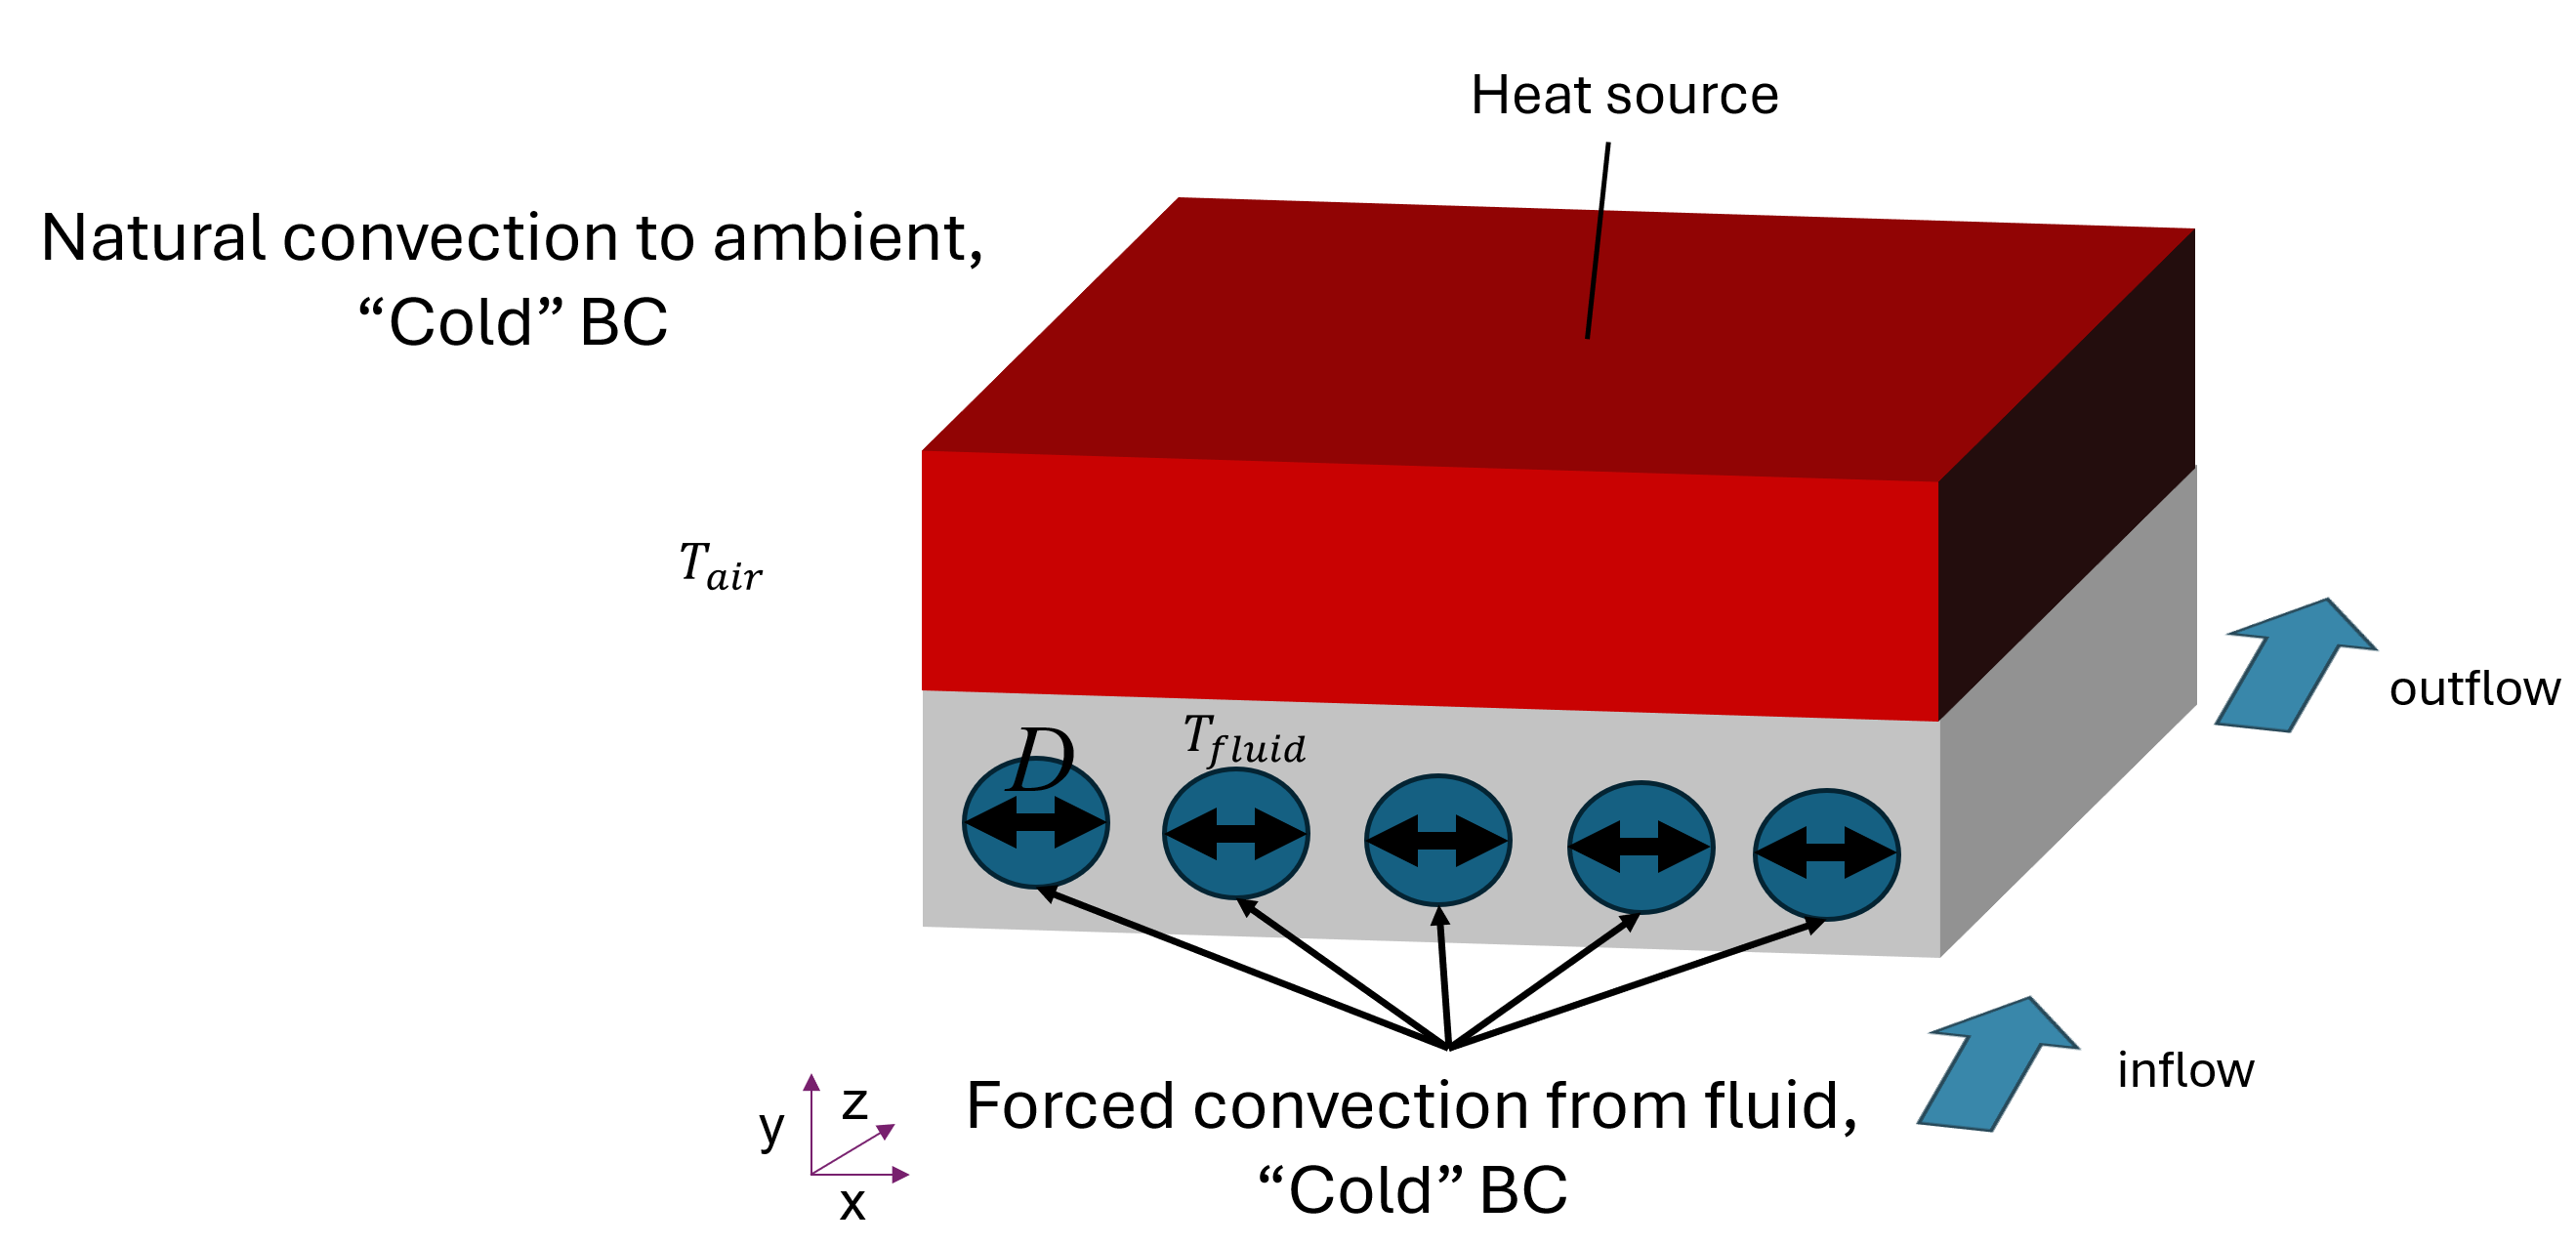

The maximum temperature in the top block is computed via a [finite element](https://www.mathworks.com/discovery/finite-element-analysis.html) simulation using [Partial Differential Equation Toolbox™](https://www.mathworks.com/products/pde.html).

## Geometry Creation

The PDE Toolbox is unitless, we choose SI units for consistency.

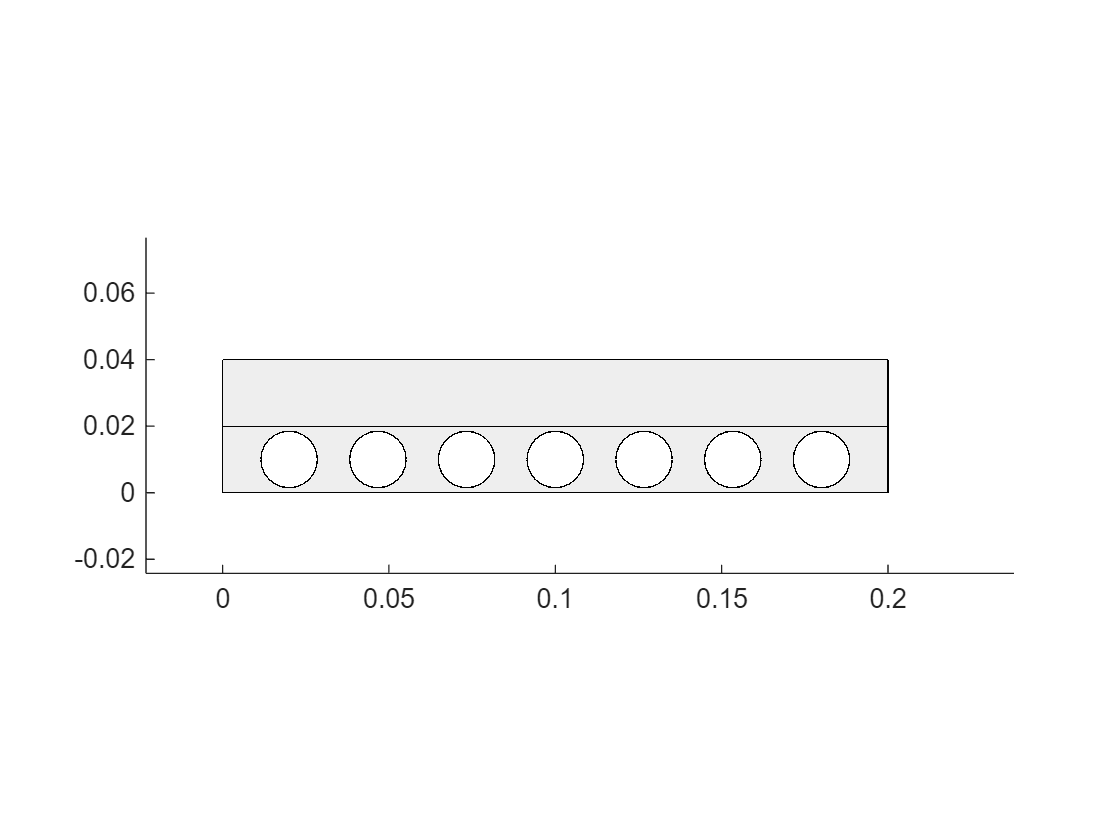

D = 0.017; % hydraulic diameter (m)
numPipes = 7;
L = 0.4; % length of pipes (m)

% run helper function to modify geometry with these parameters
gm3D = modifyGeometry(numPipes,D,L);

% visualize the geometry
pdegplot(gm3D,'FaceAlpha',0.1);
view(2) % visualize in x-y plane to easily see cooling pipes 

## Create Model and Mesh

Here, we solve the steady heat equation,

 $-\nabla\cdot(k\nabla T) = Q$,

so we choose the analysis type 'thermalSteady'. 

model = femodel("AnalysisType","thermalSteady","Geometry",gm3D);
pipeFaces = setdiff(1:gm3D.NumFaces,1:11); % find which faces correspond to pipes for when we set BCs
model = generateMesh(model);

## Problem setup 

We continue to define the problem by setting material properties, heat source, and boundary conditions.

#### Define Material Properties

% set thermal conductivities of each block
kBlockWithPipes = 0.5; % thermal conductivity of bottom block (W/(m*K))
kBlockWithHeat = 80; % thermal conductivity of top block (W/(m*K))
model.MaterialProperties(1) = materialProperties("ThermalConductivity",kBlockWithPipes); % block with pipes
model.MaterialProperties(2) = materialProperties("ThermalConductivity",kBlockWithHeat); % block producing heat

#### Define Heat Load

In this set up, we set a heat source on the block sitting on top of the block with cooling pipes.

% Set Heat Load in the top block
powerWattage = 0.5E3; % Power (W)
volCell2 = 0.02*0.2*0.4; % Volume (m^3)
heatSource = powerWattage/volCell2; % Heat source (W/m^3)
model.CellLoad(2) = cellLoad("Heat",heatSource);

#### Set Boundary Conditions

In this problem, we have ambient convection of the blocks with the air, and forced convection of the cooling liquid moving through the pipes. For convective heat flux through the boundary $htc(T-T_\infty)$, we need to specify the heat transfer coefficient $htc$ and the ambient temperature $T_\infty$. 

First we must estimate the heat transfer coefficient $htc_1$ between the fluid and the block. We do so using the Nusselt number (Nu), which we compute from Dittus-Boelter equation: 

$\textrm{Nu}=0\ldotp 023{\textrm{Re}}^{0\ldotp 8} \Pr^{0\ldotp 4}$,

where Re is the Reynolds number, Pr is the Prandtl number, $D$ is the hydraulic diameter, $L$ is the pipe length, and the ratio $\mu_b/\mu_w$ is the ratio of the viscosity in the bulk to that at the wall. 

The Reynolds number can be computed from the mass flow rate $\dot{m}$:

$Re = \frac{4\dot{m}}{\pi D \mu}$,

where $\mu$ is the dynamic viscosity. 

Given the Nusselt number, the heat transfer coefficient can be computed via the relationship:

$Nu = \frac{htcD}{k}$. 

LD_ratio = D/L; % ratio of diameter to length
m_dot = 0.02; % mass flow rate (kg/s)
mu = 0.001002; % dynamic viscosity (kg/(m*s)) of water at 20C
Re = (4*m_dot)/(pi*D*mu) % Reynolds number

Re = 1.4949e+03

Pr = 7.2 % Prandtl number of water at 20C

Pr = 7.2000

The Dittus-Boelter equation is only valid for the following conditions:


$$0\ldotp 6\le \Pr \le 160$$



$$\textrm{Re}\ge 10,000$$


$\frac{L}{D}\ge 10$.

Holding $L = 0.4$ and letting $D$ vary between $0<D\le 0\ldotp 019$, then $\frac{L}{D}\ge 21\ldotp 0526\ldotp$ Therefore, if $\textrm{Re}\ge 10,000$, we use the Dittus-Boelter equation, and if $\textrm{Re}<10,000$, we assume $\textrm{Nu}=3\ldotp 66$.

if Re >= 10000
    Nu = 0.023*Re^0.8*Pr^0.4;
else
    Nu = 3.66;
end
k = 0.598; % thermal conductivity of water at 20 C (W/(m*K))
htc = (Nu*k)/D % heat transfer coefficient

htc = 128.7459

Set the convective BCs.

% Natural convection to ambient
model.FaceLoad(1:11) = faceLoad("ConvectionCoefficient",20,"AmbientTemperature",298.15); % free heat transfer coefficient of air, room temperature
% Forced convection of chilled water in pipe
model.FaceLoad(pipeFaces) = faceLoad("ConvectionCoefficient",htc,"AmbientTemperature",278.15); % forced convection coefficient of water, temperature of the water

## Solve the model

Solve for the temperature over the entire domain. 

R = solve(model)

R =   SteadyStateThermalResults with properties:

    Temperature: [158541×1 double]
     XGradients: [158541×1 double]
     YGradients: [158541×1 double]
     ZGradients: [158541×1 double]
           Mesh: [1×1 FEMesh]


## Visualize and Post-process

Visualize the temperature distribution on the domain. Compute the maximum temperature of the block with heat source. Experiment with different number of pipes, hydraulic diameters, and mass flow rates. What happens to the maximum temperature?

blockNodes = findNodes(model.Mesh,"region","Cell",2);
Tmax = max(R.Temperature(blockNodes))

Tmax = 344.1666

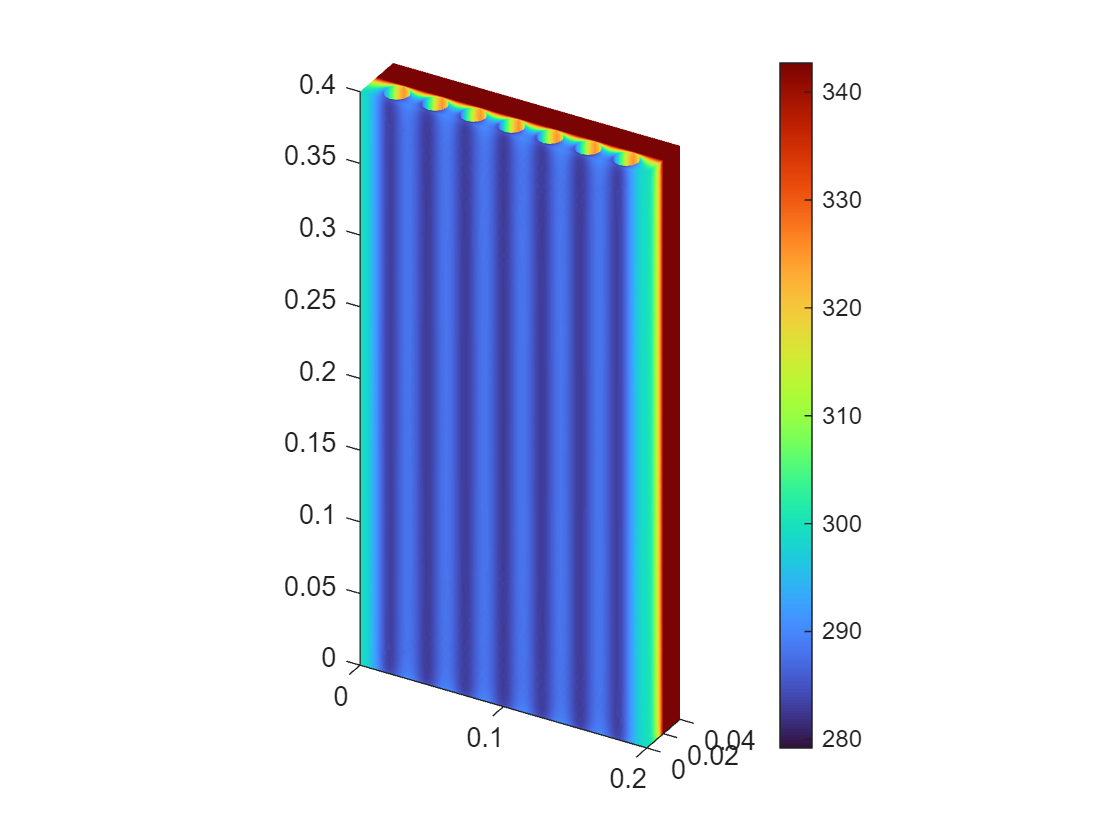

% Data to visualize
meshData = R.Mesh;
nodalData2 = R.Temperature;

% Create PDE result visualization
resultViz2 = pdeviz(meshData,nodalData2, ...
    "ColorLimits",[279.2 342.7]);


% Clear temporary variables
clearvars meshData nodalData2

## Helper Functions

function gm3D = modifyGeometry(numPipes,pipeDiameter,pipeLength)
    W = 0.2; % Cooling plate width (m)
    edgeGap = W*0.1;
    
    % First create 2D geometry
    R1 = [3; 4; 0; W; W; 0; 0; 0; 0.02; 0.02]; % create bottom rectangle
    R2 = [3; 4; 0; W; W; 0; 0.02; 0.02; 0.04; 0.04]; % create top rectangle
    Ci = zeros(size(R1,1),numPipes); % create circles for pipes
    Ci(1,:) = 1;
    Ci(2,:) = linspace(edgeGap, W-edgeGap, numPipes);
    Ci(3,:) = 0.01;
    Ci(4,:) = pipeDiameter/2;
    
    gdm = [R1,R2,Ci];
    sf = join(["(R1+R2)","C"+string(1:numPipes)],"-");
    ns = char(["R1"; "R2"; "C"+string(1:numPipes)']);
    g = decsg(gdm,sf,ns');
    gm2D = fegeometry(g);

    % extrude by length to create 3D geometry
    gm3D = extrude(gm2D,pipeLength);
end